# Part II - Model Testing and Validation

## Methods of testing

Consider a hypothetical dataset with information on 1000 patients. 

- **Hold out validation:** build a model from the first 500 patients and test on the next 500.

- **Ten fold cross validation:**  build a model from the first 900 patients and test on the next 100, then build a model using data from patients 101-1000 and test on the first 100, and so on until you cover the whole dataset.

- **Re-substitution (weakest method)**: train on data from all 1000 patients and test on the same dataset.

- **Independent validation (strongest): **use data from a different study to test the model.

## Metrics for evaluating accuracy

Continuous response data (e.g. levels of blood glucose)

- **Pearson's Correlation:** measures the strength and direction of a linear relationship between two variables.

- **Rank Correlation:** measures the strength and direction of a monotonic relationship between two variables.

- **Root Mean Square Error (RMSE): **measures the standard deviation of the residuals. Residuals represent the difference between predicted values and observed values. 


$$\mathrm{RMSE}=\sqrt{\frac{\left({\sum_{i=1}^n \left({\hat{y} }_i -y_i \right)}^2 \right)}{n}}$$


Discrete datasets (e.g. Normal vs Diabetes)

- **Accuracy:** the ratio of correct predictions to the total observations.

- **Precision:** the ratio of true positives to the total predicted positives.

- **Recall:** the ratio of true positives to the total actual positives. Also known as sensitivity. 

There is no single metric that gives an overall picture of accuracy. It is necessary to use a range of metrics to get a holistic picture.

## Testing regression models using hold out validation

Consider BMI to be a function of age, sex, glucose, cholesterol, and systolic blood pressure. How can we use these variables to determine BMI?

Begin by uploading the Framingham dataset, extracting the desired variables, and removing the rows containing NaN values.

fram = readtable("../frmgham.xls");

fram_revised =[fram.BMI,fram.AGE,fram.SEX,fram.GLUCOSE,fram.TOTCHOL,fram.SYSBP];

fram_noNaN = rmmissing(fram_revised);

Now store the BMI and the predictors into separate variables. 

X = fram_noNaN(:,2:end);
Y = fram_noNaN(:,1);

Recall from last lecture that we can use the `fitlm` function to create a linear regression model. 

model = fitlm(X,Y)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       19.817       0.33998      58.29              0
    x1             -0.027034      0.004449    -6.0765     1.2734e-09
    x2              -0.77047      0.078443    -9.8219     1.1467e-22
    x3             0.0077801     0.0015712     4.9518      7.474e-07
    x4             0.0052678    0.00087394     6.0276     1.7225e-09
    x5              0.049713     0.0018665     26.634    4.6066e-151


Number of observations: 10021, Error degrees of freedom: 10015
Root Mean Squared Error: 3.86
R-squared: 0.0865,  A

The linear regression model is represented by $y=19\ldotp 817-0\ldotp 027X_1 -0\ldotp 77X_2 +0\ldotp 008X_3 +0\ldotp 005X_4 +0\ldotp 05X_5$. This model uses the entire predictor dataset, `X`, to create a best fit line for BMI. 

When using the hold out validation method, a portion of the data is used as the training set while the rest is held out to be used as the testing test. 

We have created a custom function for generating the training and test sets called `trainTestSplit`. Use the `open` function to view the script for `trainTestSplit`. 

open trainTestSplit.mlx

The `trainTestSplit` function randomly assigns rows from our two datasets (*X, Y*) into the training and test sets, whose sizes are determined by our input for the `trainSize`. 

Use `trainTestSplit` to perform hold out validation by training on 2/3 of the dataset and testing on the remainig 1/3. 

[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.667);

Now that the datasets have been divided, we can use the `fitlm `function again to create a new linear regression model with the training dataset. 

model_train = fitlm(Xtrain,Ytrain)

model_train = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)       19.917      0.41919     47.513              0
    x1             -0.027075    0.0054949    -4.9272     8.5412e-07
    x2              -0.76918     0.096517    -7.9694     1.8619e-15
    x3             0.0068483     0.001955     3.5029     0.00046317
    x4             0.0044961    0.0010768     4.1754     3.0124e-05
    x5              0.050852    0.0023084     22.029    7.1008e-104


Number of observations: 6684, Error degrees of freedom: 6678
Root Mean Squared Error: 3.89
R-squared: 0.0856,  Adjus

### Evaluating accuracy in the test set

The model's predicted values for `Y` can be calculated using the `predict` function. Use this function to evaluate the model given the `Xtest` dataset.

Ypred = predict(model_train,Xtest);

How do the values in `Ypred` compare to the actual BMI values in `Ytest`? Use the `plot` function to compare.

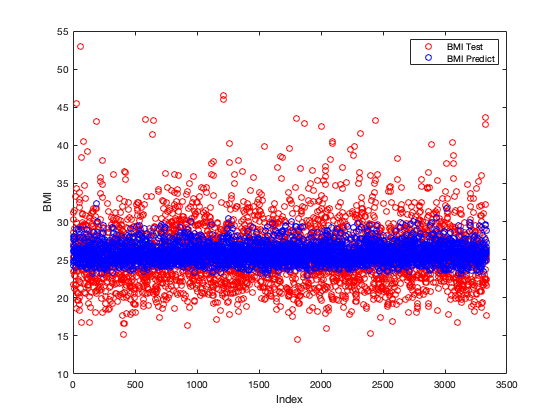

plot(Ytest,"ro")
xlabel('Index')
ylabel('BMI')
hold on
plot(Ypred, "bo")
legend('BMI Test','BMI Predict')
hold off

The predicted BMI values are in the same range as the actual values. However, the predicted dataset has much less variance and does not contain any outliers. To quantify the strength of the relationship between the BMI and predictor variables, we can calculate the correlation factors for the test and predicted datasets.

corr(Xtest,Ytest)

ans =     0.0572
   -0.0775
    0.0984
    0.0975
    0.2653


corr(Xtest,Ypred)

ans =     0.1895
   -0.2620
    0.2783
    0.2448
    0.9172


The correlation values between `Xtest` and `Ypred` are higher across the board compared to `Ytest`. There are several other parameters we can calculate to examine the model.

- Percent Error

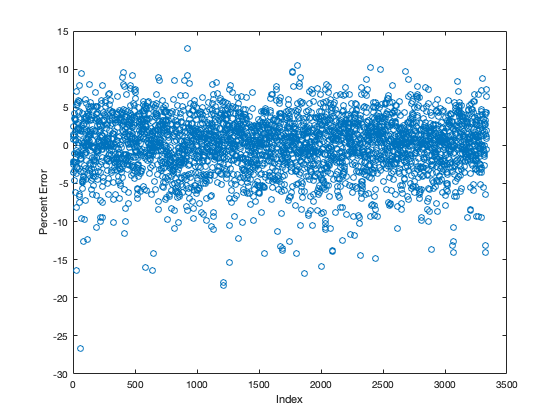

prcnt_error = (Ypred-Ytest); %should this be divided by Ytest and x100?
plot(prcnt_error,'o')
xlabel('Index')
ylabel('Percent Error')

- Percent Average Error

prcnt_avg_error = mean(Ypred-Ytest)

prcnt_avg_error = -0.0304

- Root Mean Square Error (RMSE)

RMSE = sqrt(mean((Ypred-Ytest).^2))

RMSE = 3.8119

RMSE is sensitive to large errors because the squaring process gives disproportionate weight to very large errors. Further, the RMSE can only be compared between models whose errors are measured in the same units. There is no absolute criterion for a "good" value of RMSE; it depends on the units in which the variable is measured and on the degree of predictive accuracy.

### Testing Using Cross Validation

We will now repeat the previous analysis using five fold cross validation. For this analysis, the dataset will be broken into five groups of equal size, called folds. We will train the model wth 80% of the dataset and test the model with the remaining 20%. This process will be repeated five times so that a model is created for each test set. 

Note that if there is any sort of ordering to the data, we cannot simply split the first 80% into the training set and the last 20% into the test set. It is better to populate the training and test sets by randomly ordering or shuffling the dataset first. There are a number of ways to randomize data in MATLAB. One method is shown below:

shuffled = fram_noNaN(randperm(size(fram_noNaN,1)),:);

There are several functions in MATLAB built for generating training and test sets, and they often shuffle the data internally. One of these functions is `crossvalind`. The function requires inputs for the cross validation method (`'kfold'` in our case), the number of observations, and the number of folds (`k`). The output contains a randomized array of indices (varying from 1 to `k`) which are assigned to each row in the dataset and create folds of approximately equal size.

indices = crossvalind('kfold',size(fram_noNaN,1),5)

indices =      4
     1
     4
     2
     3
     2
     1
     4
     5
     2


We can see that each row in the `indices` array contains a value between 1 and 5, linking that row to a certain fold. These indices allow us to easily separate the data into the training and test sets for the five fold cross validation. Confirm that the new datasets are approximately the same size.

sum(indices==1)

ans = 2004

sum(indices==2)

ans = 2005

sum(indices==3)

ans = 2004

sum(indices==4)

ans = 2004

sum(indices==5)

ans = 2004

Now that we have a way to break the data into five folds, we can use similar steps as in the hold out validation test in order to compare the correlation and RMSE values for `Ypred` and `Ytest`. Because five separate models must be created, a for loop will be used.

First, initialize the RMSE and correlation variables. Recall that there will be one RMSE value for each model and five correlation values (one for each predictor).

RMSE = zeros(5,1);
corr_kfold = zeros(5);

Initializing a variable prior to the for loop helps improve the speed of the script. Instead of having to reallocate memory each iteration for the growing matrix, the matrix zeros are simply replaced with the new values. However, it is important that the matrix is initialized to the correct size.

The for loop will uses the indices to determine the training and test sets for each iteration, calculate the correlation and RMSE values as we did previously, and store them in the matrices that we initiliazed. For example, in the first iteration, every row with an assigned index of 1 is treated as the test set, while the remaining data is assigned to the training set. In the second iteration, rows with an index of 2 are used for the test set, and while those with an index of 1, 3, 4 and 5 comprise the training set. 


for i = 1:5
    test = (indices == i);
    train = ~test;
    
    xtrain = X(train,:);
    ytrain = Y(train,:);
    model = fitlm(xtrain,ytrain);
    
    xtest = X(test,:);
    ytest = Y(test,:);
    ypred = predict(model,xtest);
    corr_kfold(1:5,i) = corr(xtest,ypred);
    RMSE_kfold(i) = sqrt(mean((ypred-ytest).^2));
end

Now print the correlation and RMSE variables for each of the five models.

corr_kfold

corr_kfold =     0.1792    0.1859    0.1913    0.1683    0.2516
   -0.2391   -0.2460   -0.2646   -0.2515   -0.2791
    0.1978    0.2817    0.3401    0.2823    0.2970
    0.2652    0.2607    0.2524    0.2762    0.2969
    0.9194    0.8983    0.9012    0.9003    0.9086


RMSE_kfold

RMSE_kfold =     3.7604    3.8543    3.8195    4.0335    3.8425


# Would you take the average correlation and RMSE values here?

## Evaluating discrete datasets using hold out validation

Similar methods can be used to evaluate discrete datasets, where the data can only take on certain values. An example would be classifying patients with diabetes versus those without diabetes. The values can only be one of two numbers: 0 (non-diabetic) or 1 (diabetic).

How well can we predict diabetes from the patients' glucose levels? Since we are using the hold out method, we can incorporate the `trainTestSplit` function again. This time, create a training set with 80% of the dataset. 

fram_discrete = rmmissing([fram.GLUCOSE, fram.DIABETES]);
gluc = fram_discrete(:,1);
diab = fram_discrete(:,2);
[Xtrain_discrete, Ytrain_discrete, Xtest_discrete, Ytest_discrete] = trainTestSplit(gluc,diab,0.8);

Recall from the last lecture that we used the `mnrfit` function for analyzing discrete categorical data. This function returns an array of coefficients which represent the predictor variable's effect on the relative risk of being in one category versus another. Note that the response variable, diabetes, must first be converted into a categorical array with the `categorical` function.

Ytrain_cat = categorical(Ytrain_discrete);
[b,~,stats] = mnrfit(Xtrain_discrete,Ytrain_cat)

b =     8.5116
   -0.0563


stats = struct with fields:
         beta: [2×1 double]
          dfe: 8148
         sfit: 1.1501
            s: 1
      estdisp: 0
         covb: [2×2 double]
    coeffcorr: [2×2 double]
           se: [2×1 double]
            t: [2×1 double]
            p: [2×1 double]
        resid: [8150×2 double]
       residp: [8150×2 double]
       residd: [8150×1 double]


The last category is used as the reference category, which in this case is diabetic. The first term in `b` is the intercept term of the relative risk model. The resulting equation is: $\mathrm{ln}\left(\frac{\pi_{\mathrm{normal}} }{\pi_{\mathrm{diabetic}} }\right)=8\ldotp 5444-0\ldotp 0564X_1$. The relative log odds of being normal versus diabetic decreases 0.0565 times with a one-unit increase in $X_1$, assuming all else is equal. Here $X_1$ is our only predictor variable, glucose. While this does not seem like a strong relationship, the model makes sense. Diabetic patients typically have higher glucose levels, so for every unit increase in glucose, there is a lesser chance that the patient is non-diabetic. 

The `mnrfit` function also outputs several other statistical parameters, such as the *p* value.

stats.p

ans = 	1.0e+-117 *

    0.0000
    0.1127


The *p *value for glucose is well above the accepted value of 0.05, meaning it is statistically insignificant and we fail to reject the null hypothesis that there is no relationship between diabetes and blood glucose levels.

Repeat the hold out validation test, but this time use BMI, glucose and cholesterol to predict diabetes. What is the equation for this model and which variable has the greatest effect on predicting BMI? Also, which variables are statistically significant?

fram_discrete_2 = rmmissing([fram.GLUCOSE, fram.BMI, fram.TOTCHOL, fram.DIABETES]);
X_discrete = fram_discrete_2(:,1:3);
Y_discrete = fram_discrete_2(:,4);
[Xtrain_discrete_2, Ytrain_discrete_2, Xtest_discrete_2, Ytest_discrete_2] = trainTestSplit(X_discrete,Y_discrete,0.8);
Ytrain_cat_2 = categorical(Ytrain_discrete_2);
[b_2,~,stats_2] = mnrfit(Xtrain_discrete_2,Ytrain_cat_2)

b_2 =    10.4550
   -0.0563
   -0.0678
   -0.0000


stats_2 = struct with fields:
         beta: [4×1 double]
          dfe: 8013
         sfit: 1.1391
            s: 1
      estdisp: 0
         covb: [4×4 double]
    coeffcorr: [4×4 double]
           se: [4×1 double]
            t: [4×1 double]
            p: [4×1 double]
        resid: [8017×2 double]
       residp: [8017×2 double]
       residd: [8017×1 double]


stats_2.p

ans =     0.0000
    0.0000
    0.0000
    0.9746


Based on the results, the model's equation should look similar to this: $\mathrm{ln}\left(\frac{\pi_{\mathrm{normal}} }{\pi_{\mathrm{diabetic}} }\right)=10\ldotp 918-0\ldotp 0591X_1 -0\ldotp 0699X_2 -0\ldotp 001X_3$. Our model suggests that BMI has the greatest impact towards being diabetic or non-diabetic. We would reject the null hypothesis for glucose and BMI, and fail to reject for total cholesterol.

## Estimating model accuracy in test data

The model accuracy can be evaluated using the test sets that we created, along with the `mnrval` function. Recall that this function returns the predicted probabilities for the logistic regression model given certain values for the predictor variables, which come from the predictor test set.

probability = mnrval(b_2,Xtest_discrete_2);

Let's look at the first ten rows of the predicted diabetes classifications.

probability(1:10,:)

ans =     0.9734    0.0266
    0.9880    0.0120
    0.9941    0.0059
    0.9936    0.0064
    0.9773    0.0227
    0.9790    0.0210
    0.9887    0.0113
    0.9930    0.0070
    0.9916    0.0084
    0.9812    0.0188


The left column shows the probability, based on our model, that the patient is non-diabetic. The right colum shows the probabilty that they are diabetic. 

In order to compare the predicted values to the test values, round the predicted values to the nearest integer (0 or 1). The model accuracy can then be determined by checking how many rows in the predicted and test sets match. We want to use the second column from the `probability` matrix because in that case, a 0 will indicate non-diabetic and 1 will indicate diabetic, which is the same system as the test dataset.

Ypred_round = round(probability);
accuracy = sum(Ypred_round(:,2) == Ytest_discrete_2)/length(Ypred_round) %sum(Ypred==Ytest) must be divided by number of observatios, correct?

accuracy = 0.9611

Now repeat this test using 10 fold cross validation. A for loop similar to the one used in the previous kfold example can be used. 

indices_discrete = crossvalind('kfold',size(fram_discrete_2,1),10);
b_kfold = zeros(4,10);
p_values = zeros(4,10);
accuracy_kfold = zeros(1,10);

for i = 1:10
    test_kfold = (indices_discrete == i);
    train_kfold = ~test_kfold;
    
    xtrain_kfold = X_discrete(train_kfold,:);
    ytrain_kfold = Y_discrete(train_kfold,:);
    
    y_categories = categorical(ytrain_kfold);
    
    [b_kfold(1:4,i),~,stats_kfold] = mnrfit(xtrain_kfold,y_categories);
    p_values(1:4,i)= stats_kfold.p;
    
    xtest_kfold = X_discrete(test_kfold,:);
    ytest_kfold = Y_discrete(test_kfold,:);
    
    probability_kfold = mnrval(b_kfold(:,i),xtest_kfold);
    ypred_kfold = round(probability_kfold(:,2));
    accuracy_kfold(1,i) = sum(ypred_kfold == ytest_kfold)/length(ypred_kfold);
end

We can now see the predictor coefficients, *p *values and accuracy for each of the ten models.

b_kfold

b_kfold =    10.6756   10.2466   10.7265   10.3690   10.5804   10.8774   10.5662   10.7025   10.8288   10.4085
   -0.0569   -0.0554   -0.0559   -0.0559   -0.0556   -0.0572   -0.0582   -0.0580   -0.0573   -0.0565
   -0.0683   -0.0709   -0.0674   -0.0608   -0.0656   -0.0704   -0.0648   -0.0681   -0.0728   -0.0602
   -0.0011    0.0005   -0.0017   -0.0010   -0.0014   -0.0016   -0.0002   -0.0008   -0.0009   -0.0009


p_values

p_values =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3993    0.7437    0.1825    0.4328    0.3055    0.2220    0.8969    0.5313    0.5283    0.4855


accuracy_kfold

accuracy_kfold =     0.9770    0.9701    0.9701    0.9770    0.9681    0.9790    0.9541    0.9750    0.9631    0.9661


# Again, should we just take the mean of these values?

## Additional metrics to evaluate accuracy

Confusion matrices are useful tools for evaluating how well a classification model performs. The `confusionchart` function allows us to visually compare the classifications of the predicted and test datasets.

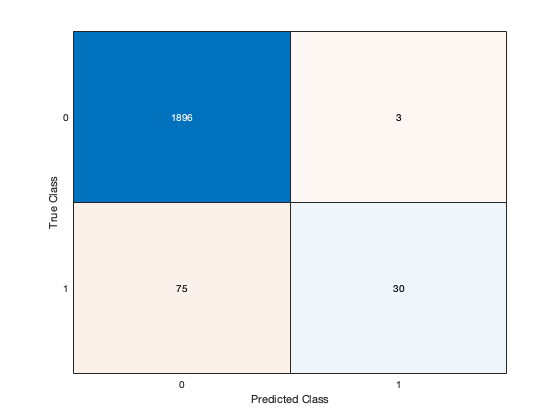

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


confusionchart(Ytest_discrete_2,Ypred_round(:,2))

There are four sections in the confusion matrix:

- **True positive (TP)** - the model predicts TRUE and the actual outcome is TRUE 

- **True negative (TN)** - the model predicts FALSE and the actual outcome is FALSE 

- **False positive (FP)** - the model predicts TRUE and the actual outcome is FALSE 

- **False negative (FN) **- the model predicts FALSE and the actual outcome is TRUE 

Using the values in the confusion matrix or the model variables (`Ypred` and `Ytest`), calculate the following parameters:

- **Precision **- the number of times that the model correctly predicted diabetes over the total number of times that the model predicted diabetes.

precision = sum(Ypred_round(:,2)==1 & Ytest_discrete_2==1)/sum(Ypred_round(:,2)==1)

precision = 0.9091

This is equivalent to the following calculation from the confusion matrix: $\mathrm{precision}=\frac{29}{\left(29+2\right)}=0\ldotp 9355$

- **Recall **- the number of times the model correctly predicted diabetes over the total number of diabetes cases in the test set. 

recall = sum(Ypred_round(:,2)==1 & Ytest_discrete_2==1)/sum(Ytest_discrete_2==1)

recall = 0.2857

This is equivalent to the following calculation from the confusion matrix: $\mathrm{recall}=\frac{29}{\left(56+29\right)}=0\ldotp 3412$

## Outcome: model testing and validation

Errors arise due to both bad data and bad models

Need to have the right benchmark i.e. what accuracy is good enough?

**Overfitting** - model is too complex

- Solution: simplify the model, get more training data, reduce noise in the data

**Underfitting** - model is too simple

- Solution: add more features to the model, use more complex algorithms

**Confounding variables** - some features are irrelevant

- Solution: start with a strong hypothesis, use unsupervised learning methods to find relevant features,                                 make sure the training data has appropriate features and sample size

A problem can arise when you measure the generalization error multiple times on the test set, and then adapt the model and hyperparameters to produce the best model *for that set. *This means that the model is unlikely to perform as well on new data. A common solution to this problem is to have a second holdout set called the **validation set**, which is used to run a single final test against the test set to get an estimate of the generalization error. 

## Improving data quality by normalization

The reason why feature scaling is important centers on how some machine learning algorithms function. For example, many classifiers calculate the distance between two data points. If one of the features has a wide range of values, the distance will be governed by this particular feature. Therefore, the range of all features should be normalized so that each feature contributes approximately proportionately to the final distance. 